# Worksheet 2, Part 3: Verification and Validation

*Author:* Zachary del Rosario, Fall 2020 (edited Fall 2025)

*Important Note:* Worksheet 2 comes to you in **three parts**; `worksheet2_part1_assignment.mlx`, `worksheet2_part2_assignment.mlx,` and `worksheet2_part3_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- The SIR model you've been using is flawed—surprise!

- A productive mindset for model verification and validation

- How to develop *verification facts* and implement them with `assert()` statements

- Practical ways to improve and verify a model

- What it looks like when there are *physics* *missing* *from our model* (an example of *validation*)

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `action_sir.m`

- `simulate_sir.m`

- `infected.csv`

- `wave1.csv`

- `wave2.csv`

clear

set(groot, 'defaultAxesXLimMode', 'auto');
set(groot, 'defaultAxesYLimMode', 'auto');

## Table Collaboration

While working on this worksheet, we encourage you to work with students at your table (in class) or even across studios (outside class). You can ask your tablemates for help on questions, answer questions that others have, or just compare answers to get a deeper understanding of the worksheet.

To encourage you to collaborate with others, we're asking you to document the folks you worked with. (This way, *we'll know* if you didn't work with anyone....)

*(Write the names of your collaborators here!)*

## Generative AI (genAI) Usage Statement

Write a short statement about how you used genAI on this assignment. *Note*: If you don't write anything, we'll assume you used genAI to write the whole thing!!!

In the beginning, god created the heavens and the "fish and chips." 

## Model Recap - Hidden Flaws!

The previous part of the worksheet ended with a question about *confidence in model results*. Honestly, you should not have been very confident in your model results from last time! That's because we did not do any kind of model verification or validation in that part of the worksheet. 

**It turns out the model you've been using throughout Worksheet 2 is actually flawed!** In this worksheet we'll walk through principled techniques you can used to check models, discover their flaws, and fix them to build confidence in results.

Let's recap: In the previous worksheet we studied some data from a scenario and used it to fit a Susceptible, Infected, Recovered (SIR) model:

% Load the training data
%tab_data = readtable("infected.csv", "Delimiter", ",")
%W_data = tab_data.Week;
%I_data = tab_data.InfectedCount;

In the *previous* part of the notebook, we attempted to answer the following questions:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

We fit an SIR model to those data and used it to make a prediction:

% NOTE: The following is my fitted model
%beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
%gamma = 1 / 2; % Recovery rate (1 / day)
%i_1 = 2;       % Initial count of infected persons

% Define initial state
%s_1 = 100 - i_1;
%r_1 = 0;

% Run simulation
%[S_fit, I_fit, R_fit, W_fit] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30);

% Plot the fitted simulation
%figure()

%axis auto;

%plot(W_data, I_data, 'b:', 'LineWidth', 3, 'DisplayName', 'Measured'); hold on
%plot(W_fit, I_fit, 'k-', 'DisplayName', 'Simulated')

%axis auto;


%xlabel("Week")
%ylabel("Infected Persons")
%legend()
%title("Training Phase Predictions")

While the overlap of Measured and Simulated data is *encouraging*, we should maintain a healthy dose of skepticism towards these model results until we *verify* and *validate* the model.

Remember that:

- **Verification** is checking that we *implemented the model correctly*; it's an exercise in coding / math.

- **Validation** is checking that *the model represents reality*; it's an exercise in physics.

ModSim students in 2020 came up with some good mnemonics:

- Verifi**c**ation concerns **c**ode

- Vali**d**ation concerns physical **d**ata

Let's look at some examples of verification and validation!

**Verification Steps:** To build and verify a physical model, we should follow a set of steps:

- *Clearly state* the model in *abstract* terms: the full set of governing equations that define the model.

- *Implement* the model in computer code, for example Matlab

- *Decide* on a set of "facts" about the model results that should be true, based on the *abstract* definition of the model

- *Verify* that the model satisfies those "facts"

Remember that *verification* is an exercise in software development / mathematics: We are *not yet *comparing our model against physical data. Instead, we're just checking to make sure we implemented the model correctly.

For instance, with the two car train example from Worksheet 1, we know that people can only move between the two trains. One "verification fact" we can test is that the sum of people on both train cars remains *constant*. The compartmental SIR model has a similar conservation property.

Writing down a set of "facts" about our model requires that we have some knowledge about our model. For example, when we derived the SIR model equations in `sir_notebook1.mlx`, we took great pains to make sure we didn't lose any individuals. As a reminder, those equations were:


$$S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Since the change terms $\Delta I, \Delta R$ are added and subtracted are carefully balanced across the stocks, the total number of persons *should* be conserved. But we should check that our implementation actually guarantees this!

### **Exercise 1 / 7**

Write down a mathematical expression for the *total number of persons* in the SIR model, based on the stocks $S, I, R$. Compute your expression using `S_fit, I_fit, R_fit` (computed above). Does this model conserve the total number of persons?

*Total = S_fit + I_fit + R_fit    , at any time*

*The model written above does conserve the total number of persons.*

% TODO: Compute total persons, plot

% Compute total persons and plot
%T_fit = S_fit + I_fit + R_fit;
%figure()
%axis auto;

%plot(W_fit, T_fit, 'k-', 'DisplayName', 'Total Persons'); hold on
%axis auto;

%title("Total and Individual Counts");
% HINT 1: You can copy-paste plotting code from above!
% HINT 2: Your plot might end up looking "boring"....

However, as some students in 2020's class found, this conservation doesn't hold for **all parameter values:**

% NOTE: The following is my fitted model
beta = 1 / 10;  % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 16; % Recovery rate (1 / day)
i_1 = 1;        % Initial count of infected persons
n_total = 100;  % Initial population
week_end = 30;  % Simulation period

% Define initial state
s_1 = n_total - i_1;
r_1 = 0;



This is because the correctness of the $\Delta I, \Delta R$ terms is not enforced well. Let's take a look at the following code from `action_sir.m:`

% This way of enforcing invariants does not actually conserve persons!
%s_n = max(s_n, 0);
%i_n = max(i_n, 0);
%r_n = max(r_n, 0);

These lines prevent the stock values from going below zero. However, they don't prevent stocks from exceeding the total population. Your task in the next couple exercises is to adopt a "verification mindset" by (1) proactively thinking of "verification facts" to check about the model, and (2) updating the model to satisfy those "verification facts."

### "Verification facts"

When doing model verification, you should decide on a large number of "facts" that should follow from your model definition, but which are *not* a direct consequence of something you coded. For instance, if you set the initial number of infected persons to 2, it's not enough to check that `i_1 = 2`. This sort of check is *necessary* *but not sufficient* for model verification. You should instead look for "facts" that are a resulting property of how you developed the model---the conservation of total persons `S + I + R == n_total` is one such example.

*One more tip:* Another great way to verify a model is to give it to someone else and ask if it makes sense. *Peer review* is an excellent way to catch errors (it's what professional scientists do!).

Once we have identified a verification fact, we need to *implement* that fact in code. We can use inequalities to check that various properties hold. MATLAB represents "true" as the value `1`, and "false" as `0:`

1 == 1 % Will return true, which is represented as `1`

ans = logical
   1


1 == 0 % will return false, which is represented as `0`

ans = logical
   0


As you've (hopefully!) noticed, the `assert()` calls in MATLAB help keep you accountable to certain inequalities. I designed these to help you test your code quickly, but you can also use them to help verify a model! An `assert()` statement does nothing if its input is true, but halts execution and shows the message when its input is false:

*Aside:* In computational science, we could call the `1e-3` above a *tolerance.*

Let's practice thinking of verification facts!

### **Exercise 2 / 7**

What other "facts" about the SIR model could you check? Write down at least three verification facts. Describe how you would carry out these checks as `assert()` statements in MATLAB.

*Hint:* There are many other facts we could write down about the stocks. What do you know about the count of people? Think about the stocks individually, and the stocks together as the total.

- *Facts: the total amount of people should always be the same*

- *Facts: there should not be more people in any group than the total amount of people. (say we have 100 people, we can't have 120 infected)*

- *Facts: we should be negative people in any categories.*

Coming up with good verification facts is difficult. To help with this, we'll do a round of *peer review *to help improve your list of facts.

### Exercise 3 / 7

### 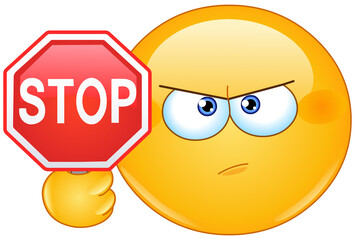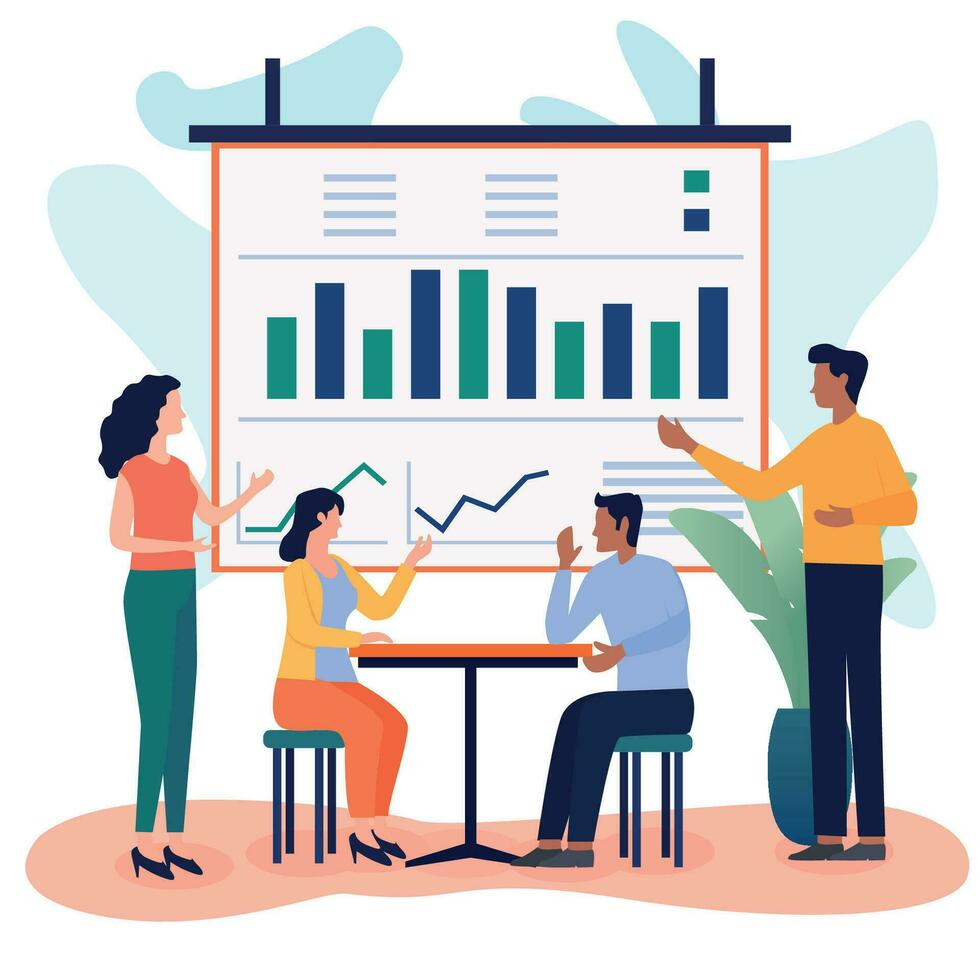

**STOP & DISCUSS:** Talk with one other person at your table and share your verification facts. First, write down their list of facts below:

(*Who did you work with?)*

*(Write your partner's list of verification facts here.)*

Next, you will analyze their list of verification facts. Use the following questions to help structure this.

- Do any of your partner's verification facts involve checking something that you **directly set** when running the model? 

-     For instance, checking that `s_1 >= 0` or `r_1 >= 0` would fall under this category, as we **directly set** `s_1, r_1` when setting up our simulation.

- *    (Identify facts from your partner that fall under this category.)*

-  **Verification facts that check directly set quantities ****are not**** effective verification facts.**

- Do any of your partner's verification facts involve checking something that is **not directly set** when running the model?

-     For instance, the state variables `S(i)` at times greater than the initial time `i > 1` are not directly set. So checking the total number of persons `S(i) + I(i) + R(i)` at all simulation times would fall under this category.

- *    (Identify facts from your partner that fall under this category.)*

-  **Verification facts that check these "indirect" properties ****are**** effective verification facts.**

**Once you've analyzed your partner's list of verification facts, share your results with them. Use your partner's results to identify the ****effective**** verification facts that you wrote down.**

Now let's put these ideas to use to fix and verify your model!

### Exercise 4 / 7

**Fix the model implementation.** Ensure that it satisfies the conservation property noted above, and all the **effective** verification facts you identified (in Exercise 2). Follow these steps to fix the model:

- Implement your verification facts as `assert()` statements in the space provided below. Target the stock values `S_fix, I_fix, R_fix.`

- Create a new function file called `action_sir_v2.m`.         *Hint:* Start by copying `action_sir.m`!

- Create a new function file called `simulate_sir_v2.m`. This can be largely the same as `simulate_sir.m`, but should call your new `action_sir_v2()` instead. *Hint:* Start by copying `simulate_sir.m`!

- Get `simulation_sir_v2()` running successfully (but not necessarily correctly!) before you try making too many changes to your action. Being able to run the code and inspect the diagnostic plots below will help with debugging your model.

**Important note:** Fixing this bug is really important, because your project will start with the code you develop here. **You will have to fix this bug in order to successfully complete the project, so please seek help from the teaching team if you're having trouble with this exercise.**

*Hint 1:* Start by copying old code! You should not write this code from scratch!

*Hint 2:* The "big thing" you need to fix is in the computation of the `infected` and `recovered` values.

*Hint 3: *You don't have access to the total population as an input, but can you *compute* it based on the inputs?

beta = 1 / 10;  % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 16; % Recovery rate (1 / day)
i_1 = 1;        % Initial count of infected persons
n_total = 100;  % Initial population
week_end = 30;  % Simulation period

% Define initial state
s_1 = n_total - i_1;
r_1 = 0;
d_1 = 0;

mu = 0.1

mu = 0.1000

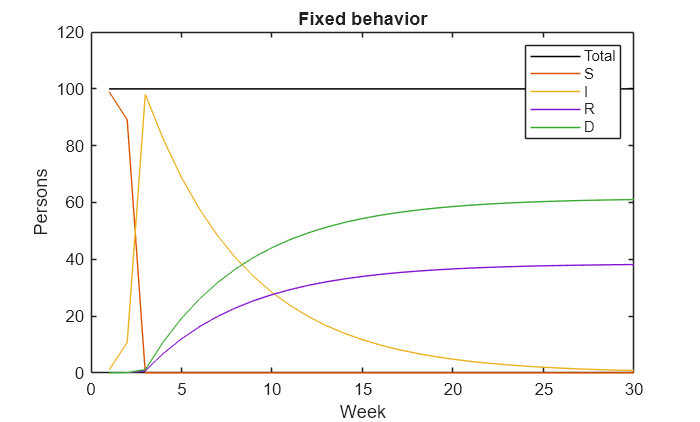


% NOTE: Do not edit this; use this to run your simulation
[S_fix, I_fix, R_fix, D_fix, W_fix] = simulate_sir(s_1, i_1, r_1,d_1, beta, gamma, mu, week_end);
T_fix = S_fix + I_fix + R_fix + D_fix;

% NOTE: Do not edit this code; Plot multiple diagnostic quantities
figure()
plot(W_fix, T_fix, 'k-', 'DisplayName', 'Total'); hold on
plot(W_fix, S_fix, 'DisplayName', 'S')
plot(W_fix, I_fix, 'DisplayName', 'I')
plot(W_fix, R_fix, 'DisplayName', 'R')
plot(W_fix, D_fix, 'DisplayName', 'D')
%S_fix
%I_fix
%R_fix
%T_fix 

xlabel("Week")
ylabel("Persons")
legend()
title("Fixed behavior")

% TODO: Write your own assertions here; use them to verify your model is correct!

all(abs(S_fix + I_fix + R_fix + D_fix - 100) < 1e-3)

ans = logical
   1


disp("you passed lol")

you passed lol


**Compare with someone else at your table: Did they manage to fix the model? If yes, how did they do it? If no, what else can you try?**